clear
clf

**Pre dimension of clamping hub with Springers**

format shortg
d_shaft_dim = [95 80 48 55 38]; % diffrent main size hubs
d_hub = 2*d_shaft_dim

d_hub =    190   160    96   110    76


**Bolt pretension**

Data

S_y = 1100; %yield strength
A_t = [245 84.3 58 20.1]; % tensile strength cross section area
d = [0.020 0.012 0.010 0.006]; % Bolt diameter metric class
p = [0.0025 0.00175 0.0015 0.001]; %  %pitch (afstand fra top til top)
A_r = [225 76.3 52.3 17.9] * (1/1000)^2; %areal fra roddiameter se table 8-1 i shigleys eller one note
d_r = sqrt(4 * A_r / pi); % root diameteren
d_m = (d + d_r)/2;      % Mean diameter
d_p = (d + d_r)/2;      % Pitch diameter
D_Km = d * 1.3          % Mean bearing diameter at the nut or at the bolt head springer side 534

D_Km =         0.026       0.0156        0.013       0.0078


d_w = [0.030 0.018 0.016 0.010]; % M20 M12 M10 M6 bolt type ISO 4762
d_h = [0.021 0.013 0.0105 0.0064];% Hole diameter
l = p; % Amount of starting leads on thread
lambda = atan(l/(pi*d_m)); %stigningsvinklen i gevind
f = 0.18; %friktionskoefficienten i gevind
fc = 0.18; %friktionskoefficienten i spændeskive
alpha = 30; %grader %30 grader er den typiske vinkel
d_c_min = [0.021 0.013 0.0105 0.0064];%0.011 %* u.mm; %mindste diameter på spændeskive
d_c_max = [0.034 0.020 0.018 0.011] %d_c_min * 1.5%0.016 %* u.mm; %største diameter på spændeskive

d_c_max =         0.034         0.02        0.018        0.011


% d_c_min * 1.5
d_c =  (d_c_min + d_c_max) / 2; %middel diameter på spændeskive
n_bolts = [4 4 4 2]; % number of bolts


**Finding pretension according to shigleys**

S_p = 0.85 * S_y; % proff strength
F_p = S_p * A_t; % proff force
F_i = 0.75 * F_p % n_bolts% nonperm

F_i =    1.7181e+05        59115        40672        14095


**Resilience of the bolt**

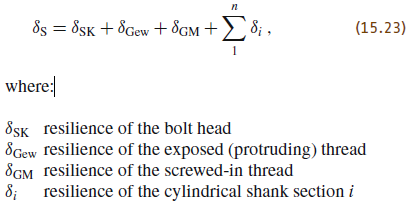

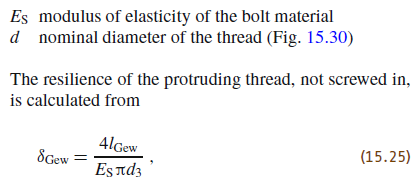

l_SK = d * 0.4; %for hexagon socket head cap screws (bolts),
E_s = 207e9;   % young modulus for the bolt for stål 207 GPa E-modul
delta_SK = 4 * l_SK/(E_s * pi * d)

delta_SK =    2.4604e-12



l_Gew = 0.017; % length of the protruding thread (not engaged)
delta_Gew = 4 * l_Gew ./ (E_s * pi * d_r)

delta_Gew =    6.1779e-12   1.0609e-11   1.2814e-11   2.1903e-11



E_M = E_s; % young modulus for the nut/hole
l_G = 0.5 * d_r % as a rule page 529. 10mm is half.

l_G =     0.0084628    0.0049282    0.0040801     0.002387


delta_G = 4 * l_G / (E_s * pi * d_r)

delta_G =    3.0755e-12



l_M = 0.33 * d % as a rule page 529.

l_M =        0.0066      0.00396       0.0033      0.00198


delta_M = 4 * l_M / (E_M * pi * d)

delta_M =    2.0298e-12



delta_GM = delta_G + delta_M

delta_GM =    5.1053e-12



l_1 = [0.0075 0.0053 0.0045 0.003]; % full threaded
d_1 = d; % full threaded
delta_i = 4 * l_1 ./ (E_s * pi * d_1) % add one for each diameter size

delta_i =    2.3066e-12   2.7167e-12   2.7679e-12   3.0755e-12



delta_S = delta_SK + delta_Gew + delta_GM + delta_i %exstendtion of the bolt

delta_S =     1.605e-11   2.0891e-11   2.3147e-11   3.2544e-11


**Resilience of the material**

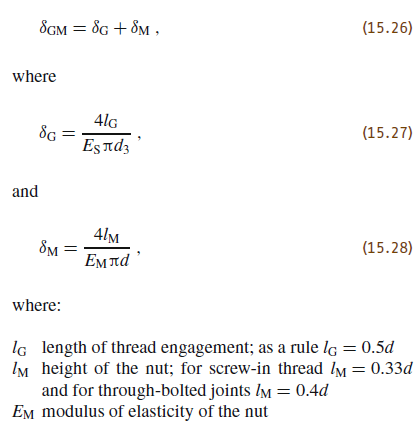

The resiliences of the individual shank areas

(15.32)

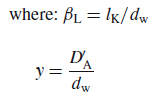

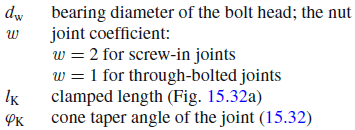

For screw in joint

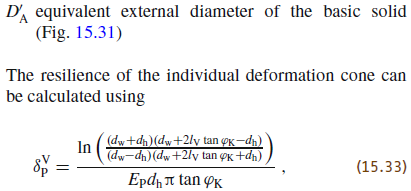

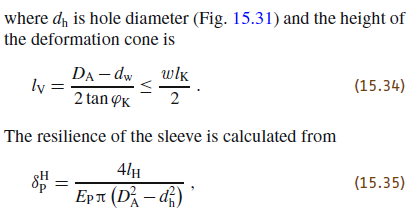

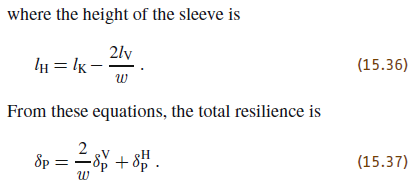

E_P = E_M

E_P =      2.07e+11


l_K = 0.026;
D_A = 0.018; % diameter ved tryk keglens max Fig. 15.31
D_A_mark = 0.018; 


beta_L = l_K ./ d_w

beta_L =       0.86667       1.4444        1.625          2.6


y = D_A_mark ./ d_w

y =           0.6            1        1.125          1.8


tan_phi_KE = 0.348 + 0.013 * log(beta_L) + 0.193 * log(y)

tan_phi_KE =       0.24755      0.35278      0.37704      0.47386


l_V = (D_A - d_w) ./ (2*tan_phi_KE) % ligning 15.34

l_V =     -0.024237            0    0.0026522    0.0084412



tan_phi_K = tan_phi_KE

tan_phi_K =       0.24755      0.35278      0.37704      0.47386




delta_V_P = log( ( (d_w + d_h) .* (d_w + 2.*l_V .* tan_phi_K - d_h) ) ./...
     ( (d_w - d_h) .* (d_w + 2*l_V .* tan_phi_K + d_h) ) ) ./...
     (E_P .* d_h .* pi .* tan_phi_K) % ligning 15.33

delta_V_P =   -2.4562e-10 + 9.2928e-10i            0 +          0i   9.2209e-11 +          0i   3.9183e-10 +          0i


delta_V_P = 0

delta_V_P =      0



l_H = 15.5 + (23+1.5)/2; %l_k - 2*l_V/w % 15.36

delta_H_P = (4 * l_H) ./ (E_P * pi .* (D_A.^2 - d_h.^2))

delta_H_P =   -1.4589e-06   1.1012e-06   7.9854e-07   6.0305e-07



w = 2; % joint coeffecient; 2 for screw-in joints, 1 for through-bolted joints

delta_P = 2/w * delta_V_P + delta_H_P

delta_P =   -1.4589e-06   1.1012e-06   7.9854e-07   6.0305e-07



f_Z = (3 + 3)*1e-6 % surface roughness 10-40

f_Z =         6e-06


F_Z = f_Z ./ (delta_S + delta_P)

F_Z =       -4.1128       5.4484       7.5135       9.9488


**Tightning torque needed found with springer**

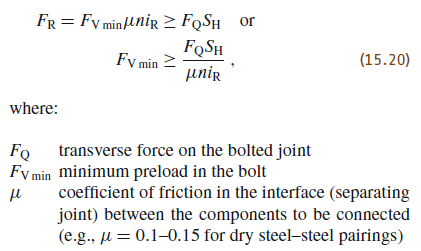

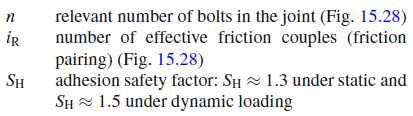

$F_A$ - additionally loaded by an axial working load 

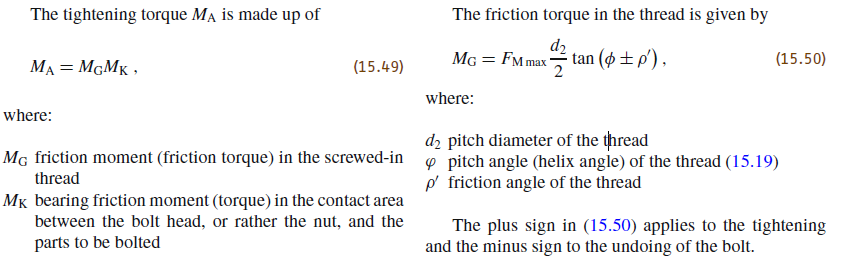

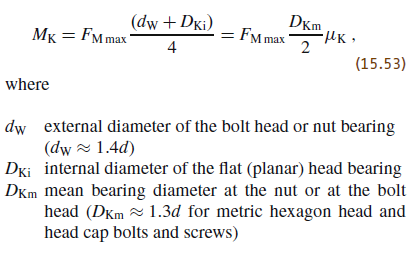

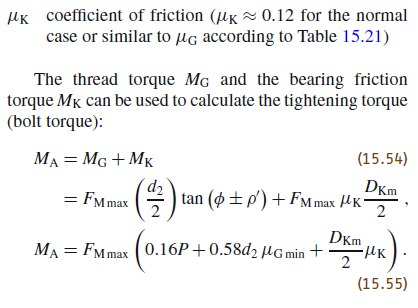

Med springer

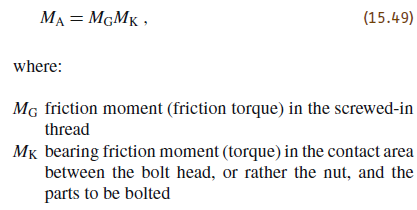

F_Z = 0; % The resulting loss of force is called the loss of preload
F_Mmin = F_i + F_Z

F_Mmin =    1.7181e+05        59115        40672        14095


alpha_A = 1.6% tightening factor % Table 15.19: Tightening with torque wrench

alpha_A =           1.6


F_Mmax = alpha_A * F_Mmin % 

F_Mmax =    2.7489e+05        94585        65076        22552


mu_G_min = 0.12; % Table 15.21 dry black tempered / steel blank
mu_K = 0.12; % for the normal case or similar to mu_G according to Table 15.21
M_A = F_Mmax .* (0.16*p + 0.58*d_p * mu_G_min + D_Km/2 * mu_K)

M_A =        892.02       186.96        107.5       22.618


Med shigleys

%funktion for forspændingsmomentet with shigleys (uniform pressure cone)
% T_for = (F_i .* d_m/2) * ((tan(lambda) + f * secd(alpha)) ./...
%     (1 - f * tan(lambda) * secd(alpha))) + (F_i * fc .* d_c)/2
% T_ = vpa(unitConvert(T, u.N * u.m), 4)
% T_bolt = T_for / n_bolts

d_shaft = [95e-3 55e-3 55e-3 60e-3]; %48e-3

"Is the friction higher then the max force from the"

ans = "Is the friction higher then the max force from the"

F_i_fric = F_i * 4 * 0.2 %f

F_i_fric =    1.3744e+05        47292        32538        11276


T_max = [5.1e3 1e3 1e3 100]; %473
F_max = T_max ./ (d_shaft/2)

F_max =    1.0737e+05        36364        36364       3333.3



F_i_max = F_max; %/ n_bolts;
F_i_fric > F_i_max

ans = 1×4 logical array
   1   1   0   1


"max torque"

ans = "max torque"

% T_max = (F_i_max .* d_m/2) * ((tan(lambda) + f * secd(alpha)) ./...
%     (1 - f * tan(lambda) * secd(alpha))) + (F_i_max * fc .* d_c)/2
" "

ans = " "

**a dobbelt check on how much torque the screws can take **

d_r % root diameter of bolt

d_r =      0.016926    0.0098564    0.0081603     0.004774


tau_max = 1100e6

tau_max =       1.1e+09


T_max_calc = tau_max / 16 * (pi * d_r.^3) % torque at max torsion

T_max_calc =        1047.3       206.81       117.37         23.5


M_A

M_A =        892.02       186.96        107.5       22.618


T_max_calc > M_A

ans = 1×4 logical array
   1   1   1   1


" "

ans = " "

**Shear and normal stress under bolts**

F_Mmax

F_Mmax =    2.7489e+05        94585        65076        22552


F_i

F_i =    1.7181e+05        59115        40672        14095


t = [0.034 0.022 0.022 0.010]; % thickness of material under bolts
w = d_w - d_h

w =         0.009        0.005       0.0055       0.0036


% A_flade = [113e-6*4 113e-6 113e-6 113e-6]; % only taken for 1kNm small
A_flade = pi*(d_w/2).^2 - pi*(d_h/2).^2 % normal force area

A_flade =     0.0003605   0.00012174   0.00011447    4.637e-05


sigma_m = F_Mmax ./ A_flade; %Normal stress
sigma_m_mpa = sigma_m * 1e-6 

sigma_m_mpa =        762.53       776.96       568.49       486.35



A_cross = t .* w % cross area of material under bolt

A_cross =      0.000306      0.00011     0.000121      3.6e-05


tau_m = F_Mmax ./ A_cross; % shear stress under bolt
tau_m_mpa = tau_m * 1e-6

tau_m_mpa =        898.33       859.86       537.82       626.45


**Pressure on small shafts**

L = [80 80 59 39]; % engaged length
d_small = [48 48 28 14]; %shaft diameter
A = L.*d_small % shadow area of shaft

A =         3840        3840        1652         546


F_Mmax

F_Mmax =    2.7489e+05        94585        65076        22552


F_Mmax = [274890 94585 94585 22552]%alpha_A * F_Mmin % 

F_Mmax =       274890       94585       94585       22552


sigma_shaft = F_Mmax*4 ./ A % normal stress on shaft

sigma_shaft =        286.34       98.526       229.02       165.22


Material needed is AISI 1141 or AISI 1137 water quenched

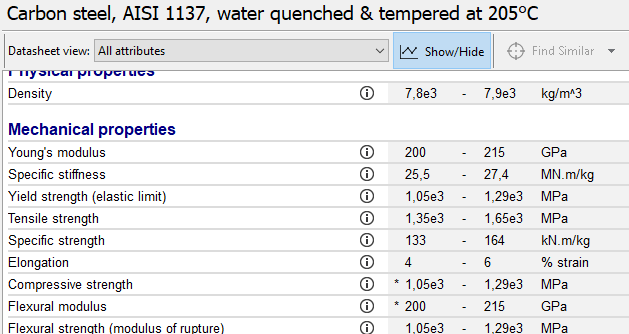

(from EduPack)

**Dynamsike krafter**

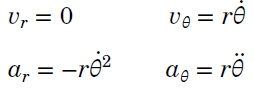

RPM = [7200 3200 1600]

RPM =         7200        3200        1600


omega = RPM / 60 * 2 * pi % angualr speed rad/s

omega =        753.98        335.1       167.55


%distance to center of mass

**top clamping piece**

Data is from solidworks

y = 0.023272; 
z = 0.00385;
r_center = sqrt(y^2 + z^2)

r_center =      0.023588


m = 1.5; %kg
a_r = r_center * omega.^2

a_r =         13410       2648.8       662.21


F_clamp = m * a_r

F_clamp =         20115       3973.2       993.31


F_clamp_bolt = F_clamp/4

F_clamp_bolt =        5028.6       993.31       248.33


**Claw piece**

y = 0.012095;
z = 0.00181;
r_center = sqrt(y^2 + z^2)

r_center =       0.01223


m = 3.3; %kg
a_r = r_center * omega.^2

a_r =        6952.4       1373.3       343.33


F_claw = m * a_r

F_claw =         22943         4532         1133


F_claw_bolt = F_claw/4

F_claw_bolt =        5735.8         1133       283.25


unbalance in force

F_total = F_claw - F_clamp

F_total =        2828.5       558.72       139.68


See that the worst case for 1kN m

is a 120 Hz, 2 pole,  FS 355 and FS 400

RPM = 7200

Torque 849

For 0.1kN m it is 120 Hz 2 pole, FS 225

RPM = 7200

Torque = 96